Load & Choose a dataset (must be run at the very start)

chosenDataset = "tubes";

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
fileLoc = sprintf("MPDD/%s/test", chosenDataset);
fileLocGT = sprintf("MPDD/%s/%s_ground_truth", chosenDataset, chosenDataset);

% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);
dsGT = imageDatastore(fileLocGT, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

Train a model on the chosen dataset (will also output a validation set that can be used for the batch testing function

% Creates an AI Model in local directory called "tubeClassifierNet.mat"
% returns a test set that was used for validation
testDS = training(ds);

Detected 4 classes to learn.


Perform a batch test on the test set

% Inspects the chosen batch using the trained AI model, outputs a confusion
% matrix
runBatchInspection(testDS);

Unrecognized function or variable 'testDS'.

Test individual images with the trained model

IMPORTANT: need to move all good images to the testing good folder, which means we can remove the testing folder altogether, this will make selecting images far easier, but would also require us to rename images in mass

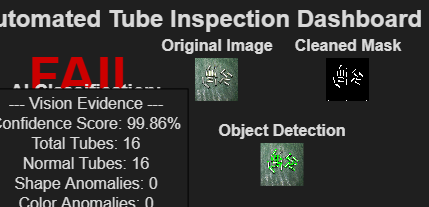

% Adjust below controls to choose a specific image of interest
imageType = "defectiveLength";
folder = sprintf("%s/MPDD/%s/test/%s", ...
    pwd, chosenDataset, imageType); % Find Folder
numFiles = numel(dir(folder)) - 2; % Count number of files in the folder
imgNum = 10;

% Find and load chosen image
fileLoc = sprintf("%s/%s%03d.png", folder, imageType, imgNum);
img = imread(fileLoc);

% Generate Output
reportData = singleImageInspectionFunction(img, true);
displayInspectionOutput(img, reportData);

#FIXME - temporary code for determining folder location, will be put to use once folder is re-organize and renamed

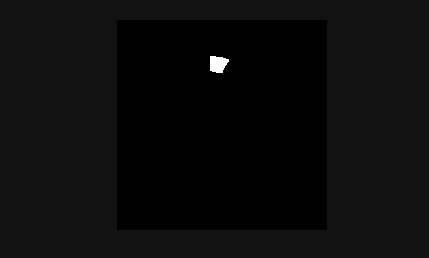

% Compare masks

folder = sprintf("%s/MPDD/%s/%s_ground_truth/%sMask", ...
    pwd, chosenDataset, chosenDataset, imageType);
fileLoc2 = sprintf("%s/%s%03dMASK.png", folder, imageType, imgNum);
img2 = imread(fileLoc2);

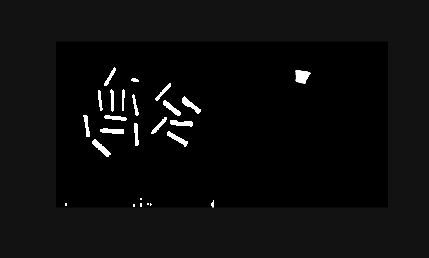



montage({reportData.images.ImageMask, img2})

title("Mask Comparison");